# SIR Notebook 3: Verification and Validation

*Author:* Zachary del Rosario, Fall 2020

*Learning Objectives:* As a result of working through this notebook, you will learn:

- A productive mindset for model verification and validation

- Example checks we can run for *verification*

- What it looks like when there are *missing physics* in our model (an example of *validation*)

## Model Recap

In the previous notebook we studied some data from a scenario and used it to fit a Susceptible, Infected, Recovered (SIR) model:

% Load the training data
tab_data_train = readtable("infected.csv", "Delimiter", ",")

tab_data_train = 6×2 table
    W    I 
    _    __

    1     2
    2     3
    3     5
    4     8
    5    11
    6    16


We fit an SIR model to those data, and used it to make a prediction.

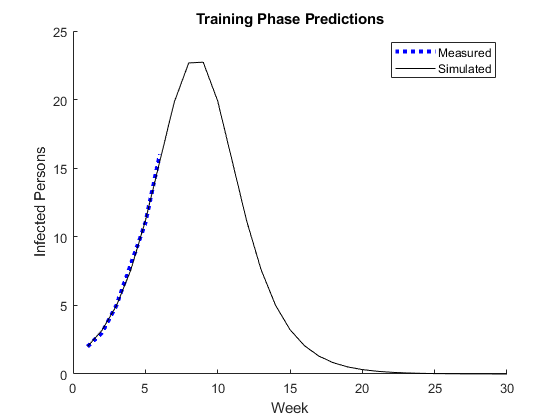

% NOTE: The following is my fitted model
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
i_0 = 2;       % Initial count of infected persons

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30);

% Plot the fitted simulation
figure(1); clf; hold on;
plot(tab_data_train.W, tab_data_train.I, 'b:', 'LineWidth', 3); label1 = "Measured";
plot(W_fit, I_fit, 'k-'); label2 = "Simulated";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Training Phase Predictions")

While the overlap of Measured and Simulated data is *encouraging*, we should maintain a healthy dose of skepticism towards these model results until we *verify* and *validate* the model.

Remember that:

- **Verification** is checking that we *implemented the model correctly*; it's an exercise in coding / math.

- **Validation** is checking that *the model represents reality*; it's an exercise in physics.

Let's look at some examples of verification and validation!

**Verification Steps:** To build and verify a physical model, we should follow a set of steps:

- *Clearly state* the model in *abstract* terms: the full set of governing equations that define the model.

- *Implement* the model in computer code, for example Matlab

- *Decide* on a set of "facts" about the model results that should be true, based on the *abstract* definition of the model

- *Verify* that the model satisfies those "facts"

Remember that *verification* is an exercise in software development / mathematics: We are *not yet *comparing our model against physical data. Instead, we're just checking to make sure we implemented the model correctly.

Remember back to the Penny Myth example: With Model 1 (the drag-free one) we *verified* our model results by checking that the distance the penny fell matched the height of the Empire State Building. That's a "fact" about the model results we know should be true, based on the way we set up the problem.

Writing down a set of "facts" about our model requires that we have some knowledge about our model. For example, when we derived the SIR model equations in `sir_notebook1.mlx`, we took great pains to make sure we didn't lose any individuals. As a reminder, those equations were:


$$S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t$$


Since the change terms $\Delta I, \Delta R$ are added and subtracted are carefully balanced across the stocks, the total number of persons should be *conserved*.

**Exercise:** Write down a mathematical expression for the *total number of persons* in the SIR model, based on the stocks $S, I, R$. Compute your expression using `S_fit, I_fit, R_fit` (computed above). Does this model conserve the total number of persons?

*(Here's some space for you to write some math using text!)*

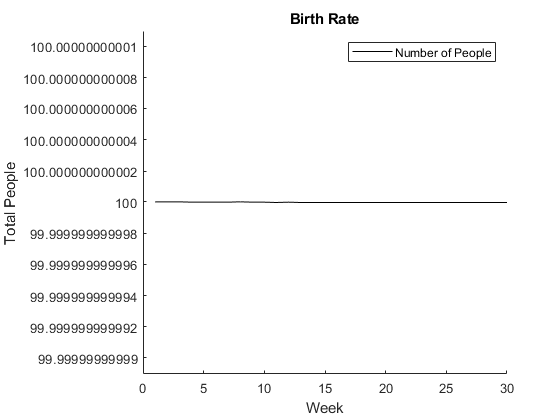

% TODO: Compute total persons, plot
% HINT 1: You can copy-paste plotting code from above!
% HINT 2: Your plot might end up looking "boring"....
figure(2); clf; hold on;
plot(W_fit, S_fit + I_fit + R_fit, 'k-'); label1 = "Number of People";

xlabel("Week")
ylabel("Total People")
legend({label1})
title("Birth Rate")

**Exercise:** What other "facts" about the SIR model could you check?

- None of the stocks should ever be anything other than a non-negative integer

- No person should ever go backwards (R -> I and/or I -> S). Ergo, S should monotonically decrease while R should monotonically increase. I will vary.

When doing model verification, you should decide on a large number of "facts" that should follow from your model definition, but which are *not* a direct consequence of something you coded. For instance, if you set the initial number of infected persons to 2, it's not enough to check that `i_0 = 2`. This sort of check is *necessary* *but not sufficient* for model verification. You should instead look for "facts" that are a resulting property of how you developed the model---the conservation of total persons is one such example.

One last tip: Another great way to verify a model is to give it to someone else and ask if it makes sense. *Peer review* is an excellent way to catch errors (it's what professional scientists do!).

Also remember that *verification* is only half of the model evaluation story; verification just checks that we *implemented* the model correctly. We should also check whether the model is a good representation of reality! To do that, we need to *validate* our model.

**Validation Steps:** To build and validate a physical model, we should follow a set of steps:

- *Clearly state* the purpose for which we want to use our model. This should include the scenario we are studying, and the questions we want to answer.

- Construct our model based on understanding of the physical phenomena at play.

- Use *training data* to fit the parameters in the model and determine if the model is *flexible* enough to represent the data.

- Use *validation data* to assess whether the model is *trustworthy* enough to support answering our questions.

The *validation data* should lie "outside" our training data, in order to test whether our model is *trustworthy *enough to extrapolate outside what we've seen before. This is important for answering the questions we have about the flu: Remember we were interested in answering:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

The training phase results are encouraging, in that they indicate the model can fit behaviors we've seen before. But what about something we haven't seen before? To test if the model is valid for predicting results in the future, we need to check it against data not used in fitting to see if the model as-fit can predict future results. To that end, let's load some additional data to serve validation purposes.

% Load the validation data
tab_data_validate = readtable("wave1.csv", "Delimiter", ",")

tab_data_validate = 18×2 table
    W     I 
    __    __

     1     2
     2     3
     3     5
     4     8
     5    11
     6    16
     7    20
     8    23
     9    23
    10    20
    11    16
    12    12
    13     8
    14     6
    15     4
    16     3


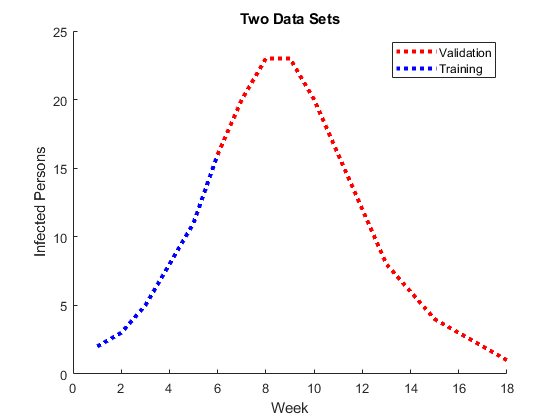


% Plot the training and validation data
figure(3); clf; hold on;
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 3); label1 = "Validation";
plot(tab_data_train.W, tab_data_train.I, 'b:', 'LineWidth', 3); label2 = "Training";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Two Data Sets")

Notice that the validation data extends beyond the training data. It's important that we do not touch the validation data at all when fitting the model.

Now let's complete the validation exercise by comparing the model against the validation data.

**Exercise:** Create a plot of `tab_data_validate` against the simulation results `W_fit, I_fit`.

*Hint:* See the code above for a hint on how to plot data using a Matlab table.

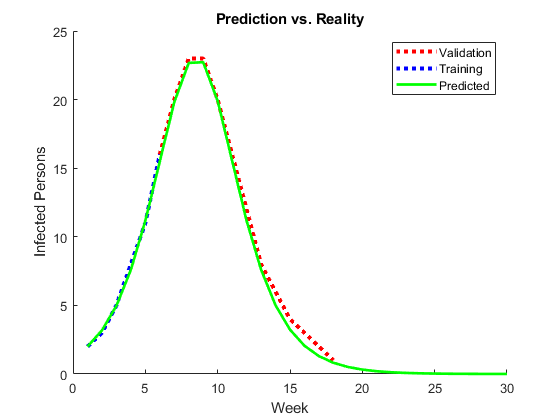


% Plot the training and validation data
figure(4); clf; hold on;
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 3); label1 = "Validation";
plot(tab_data_train.W, tab_data_train.I, 'b:', 'LineWidth', 3); label2 = "Training";
plot(W_fit, I_fit, 'g-', 'LineWidth', 2); label3 = "Predicted";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Prediction vs. Reality")

We can see the agreement between simulation and validation data is not perfect. However, it's sufficiently good to answer our questions. These results indicate that our model is valid for predicting a few weeks into the future.

**Important Note: **It may seem circular that we're using data from "the future" (beyond Week 6) to validate the model. In real cases of model validation we will take *historical* data, split it into training and validation sets, and perform the same exercise. In that case, it's important to split the data in a way that matches the way you intend to use the model; for instance, if making predictions in the future, make sure your validation data contains information further forward in time than what's contained in your training data.

**A Productive Mindset:** When building a model, we should maintain a healthy degree of skepticism towards our model. Remember, "All models are wrong, some are useful." *Verification* and *Validation* are concrete ways to put that skepticism into practice: 

Verification: By writing down and testing "facts" about our model, we are checking to make sure we did not introduce any bugs when implementing our model in code.

Validation: By "stress testing" our model with data it hasn't seen before, we can get a sense of how well our model will perform when we use it to predict on scenarios we've not yet seen. 

Verification and validation help us build confidence---but not certainty---that our model will be useful. Why should we have confidence but not certainty? Let's take a look at one way things can go wrong---when we're *missing some physics in our model.*

## Missing Physics

We've shown that the model is valid for the purpose of predicting a few weeks into the future. But what about predicting the next flu season? Let's load a second data set to see how well the model performs in that scenario:

% Load the validation data
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",")

tab_data_wave2 = 32×2 table
    W     I
    __    _

    73    1
    74    1
    75    1
    76    2
    77    2
    78    3
    79    3
    80    4
    81    4
    82    5
    83    5
    84    6
    85    6
    86    6
    87    6
    88    6


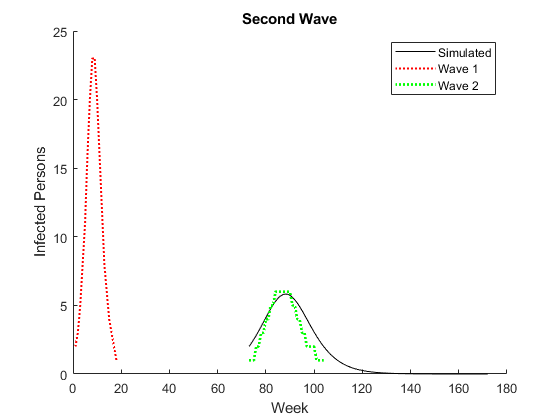


% Configure the simulation
beta = 1 / 200; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2.75; % Recovery rate (1 / day)
i_0 = 2;       % Initial count of infected persons
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_long, I_long, R_long, W_long] = sir_simulate(s_0, i_0, r_0, beta, gamma, 100);

% Plot the fitted simulation
figure(5); clf; hold on;

plot(W_long + 72, I_long, 'k-'); label1 = "Simulated";
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";
plot(tab_data_wave2.W, tab_data_wave2.I, 'g:', 'LineWidth', 2.0); label3 = "Wave 2";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Second Wave")

The model is totally invalid for predicting the next flu season!

*This is also a poor comparison, because the model expects that the outbreak starts at T = 0, where as wave 2 starts at T = ~75*

**Exercise:** Try tweaking the parameters `beta, gamma, i_0` to match this second wave phenomena. Convince yourself that it is not possible to represent both the first and second wave with the present model.

*It's not great, but I object on principle to the format of this question (although I understand its pedagogical benefit).*

Let's think about why our present model can't represent this second wave. Remember the stock and flow diagram for this model:

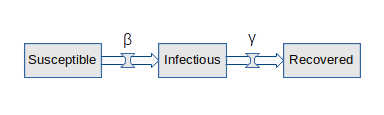

This stock and flow diagram has just two flows, Infections carry individuals from S to I, and Recoveries carry individuals from I to R. In this model *only Susceptible* *persons can become Infected*. 

**Exercise:** Answer the following questions:

- What *physical causes* could lead to a person getting re-infected with the flu? Name two or three possible causes. *Hint:* The US Centers for Disease for Disease Control and Prevention (CDC) publishes articles on [this topic](https://www.cdc.gov/flu/about/viruses/change.htm).

- *Immunity (antibodies) don't last forever, aren't 100% effective even when they do last, and the flu mutates every year so as to avoid those antibodies.*

- How could we *represent* these physical causes in our model? What *additional flow* would you add to the model, and what physical mechanism would this represent?

- *Add a flow from Recovered to Susceptible that represents immunity becoming no longer effective (either because the flu mutates or your immune system forgets).*